%% 清理
close all; clear; clc;
% 估计小车在每一时刻的位置和速度

%% 无噪音的理想值
T = (1 : 100); % 离散的时间序列，单位是s
p = zeros(1, length(T)); v = zeros(1, length(T)); 
p(1) = 0;v(1) = 3; % 小车的初始速度是5m/s，未知真实值
a = 0.1; % 加速度

for t = 2 : length(T)
    p(t) = p(t - 1) + v(t - 1) + 1/2 * a; % 理想的位置
    v(t) = v(t - 1) + a; % 理想的速度值
end

underline_x = [p; v];

%% 有噪音的实际值，模拟噪音
% 状态噪音
sigma_r =0.18

sigma_r = 0.1800

r_p = sigma_r * randn(1, length(T));
r_v = sigma_r * randn(1, length(T));
x = underline_x;
for t = 2 : length(T)
    x(1, t) = x(1, t - 1) + x(2, t - 1) + 1/2 * a + r_p(t); % 真实的位置
    x(2, t) = x(2, t - 1) + a + r_v(t); % 真实的速度值
end

% 观测噪音
sigma_Delta_p =0.01

sigma_Delta_p = 0.0100

Delta_p = sigma_Delta_p * randn(1, length(T)); % GPS测量误差，标准差为3m
z = x(1, :) + Delta_p; % GPS的观测值，带有测量误差

%% 卡尔曼滤波
% 已知量
% 已知的线性变换矩阵
F = [1, 1; 0, 1]; % 状态转移矩阵
B = [1/2; 1]; % 控制矩阵
u = a;
H = [1, 0];
sigma_Q = 0.08

sigma_Q = 0.0800

Q = [sigma_Q^2, 0; 0, sigma_Q^2]; % 过程噪声的协方差矩阵，这是一个超参数
sigma_R = 0.03

sigma_R = 0.0300

R = sigma_R^2; % 观测噪声的协方差矩阵，也是一个超参数。因为是一维的，就是一个数

% 初始化
hat_x_ = zeros(2, length(T)); hat_x = zeros(2, length(T));
hat_x(:, 1) = [0; 0]; % 初始状态，[位置, 速度]，就是我们要估计的内容
P = [0.1, 0; 0, 0.1]; % 先验误差协方差矩阵的初始值，根据经验给出

% 卡尔曼滤波5个关键公式
for t = 2:length(T)
    hat_x_(:, t) = F * hat_x(:, t - 1) + B * u;
    P_ = F * P * F' + Q;
    K = (P_ * H') ./ (H * P_ * H' + R);
    hat_x(:, t) = hat_x_(:, t) + K * (z(:, t) - H * hat_x_(:, t));
    P = (eye(2) - K * H) * P_;
end

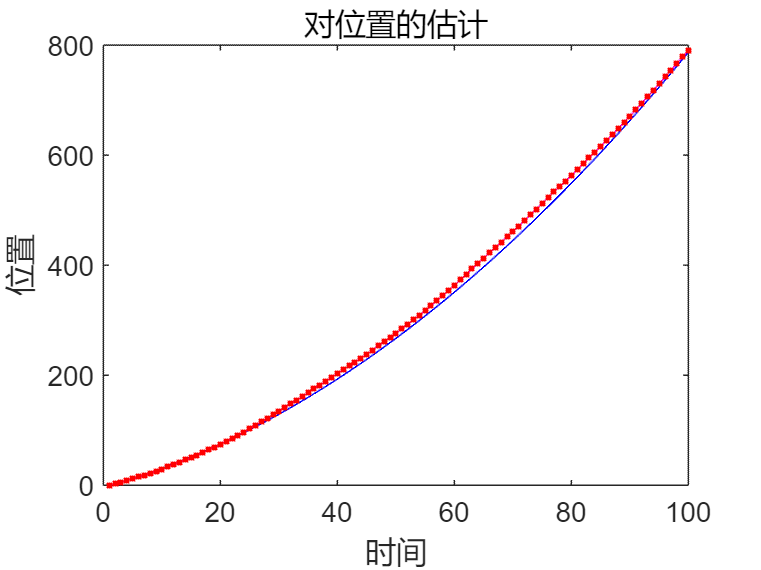

%% 绘图
figure(1);
plot(T, underline_x(1, :), 'b'); % 位置的理想值
hold on;
plot(T, x(1, :), 'g'); % 位置的实际值
plot(T, z(1, :), 'm'); % 位置的观测值
plot(T, hat_x(1, :), 'r.'); % 位置的最优估计值
title('对位置的估计');
xlabel('时间'); ylabel('位置');

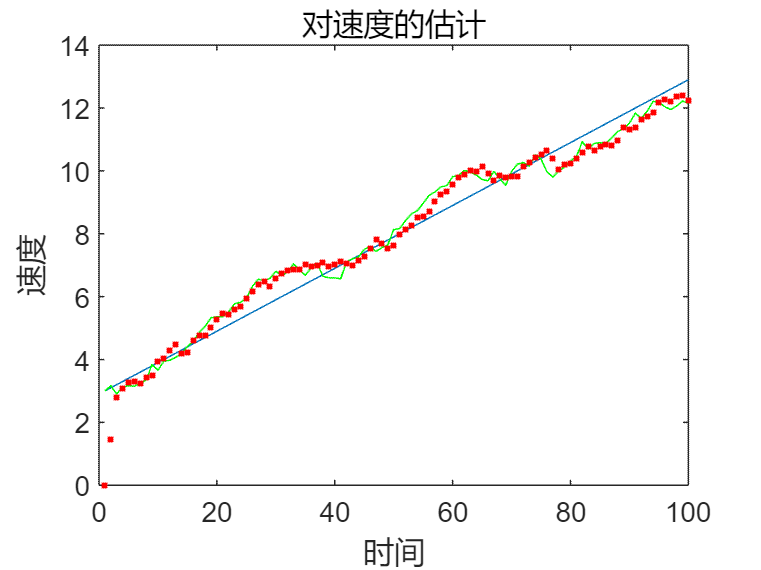


figure(2);
plot(T, underline_x(2, :)); % 速度的理想值
hold on;
plot(T, x(2, :), 'g'); % 速度的实际值
plot(T, hat_x(2, :), 'r.'); % 速度的最优估计值
title('对速度的估计');
xlabel('时间'); ylabel('速度');